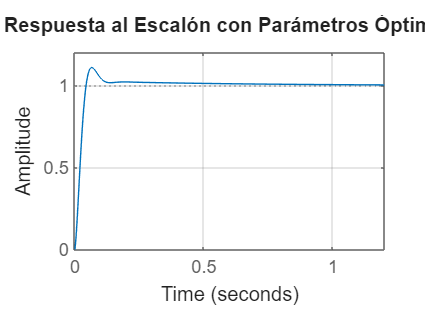


=== Parámetros Óptimos ===


Kp     = 30.0941


tau_I  = 0.6387


tau_D1 = 0.0036


tau_D2 = -0.0008



=== Métricas de Desempeño ===


Overshoot     = 11.02%


Rise Time     = 0.0310 s


Settling Time = 0.2565 s


Peak Time     = 0.0657 s


clc; clear; close all;

s = tf('s');
K = 2652.28/23;
p = 64.986;
G = K / (s * (s + p));

objective_PID = @(x) compute_cost(x, G, p, K); % Objetivo funcion fminsearch

x0 = [1, 0.05, 0.02]; \% [Kp, tau_I, tau_D1, tau_D2] Valores de busqueda de inicio
x_opt = fminsearch(objective_PID, x0);

Kp_opt     = x_opt(1);
tau_I_opt  = x_opt(2);
tau_D1_opt = x_opt(3);
tau_D2_opt = -64.986/(Kp_opt*2652.28);
tau_Dtilde_opt = tau_D1_opt + tau_D2_opt;

numerador_PID_opt = K * Kp_opt * tau_D1_opt * (s^2 + s / tau_D1_opt + 1 / (tau_D1_opt * tau_I_opt));
denominador_PID_opt = s^2 * (s + p) + K * Kp_opt * tau_Dtilde_opt * (s^2 + s / tau_Dtilde_opt + 1 / (tau_Dtilde_opt * tau_I_opt));
T_opt = numerador_PID_opt / denominador_PID_opt;

figure
step(T_opt)
grid on
title('Respuesta al Escalon con Parametros Optimos')

info_opt = stepinfo(T_opt);

fprintf('\n=== Parametros Optimos ===\n');
fprintf('Kp     = %.4f\n', Kp_opt);
fprintf('tau_I  = %.4f\n', tau_I_opt);
fprintf('tau_D1 = %.4f\n', tau_D1_opt);
fprintf('tau_D2 = %.4f\n', tau_D2_opt);

fprintf('\n=== Metricas de Desempeno ===\n');
fprintf('Overshoot     = %.2f%%\n', info_opt.Overshoot);
fprintf('Rise Time     = %.4f s\n', info_opt.RiseTime);
fprintf('Settling Time = %.4f s\n', info_opt.SettlingTime);
fprintf('Peak Time     = %.4f s\n', info_opt.PeakTime);

\%Funcion de coste
function cost = compute_cost(x, G, p, K)
    Kp = x(1);
    tau_I = x(2);
    tau_D1 = x(3);
    \%\% tau_D2 = x(4);

    if any(x <= 0)  \% evitar valores negativos o cero
        cost = 1e6;
        return;
    end
    
    tau_D2 = -64.986/(Kp*2652.28);

    tau_Dtilde = tau_D1 + tau_D2;
    s = tf('s');

    num = K * Kp * tau_D1 * (s^2 + s / tau_D1 + 1 / (tau_D1 * tau_I));
    den = s^2 * (s + p) + K * Kp * tau_Dtilde * (s^2 + s / tau_Dtilde + 1 / (tau_Dtilde * tau_I));
    T = num / den;

    info = stepinfo(T, 'SettlingTimeThreshold', 0.02);

    if isempty(info) || isnan(info.Overshoot)
        cost = 1e6;
        return;
    end

    cost = 0;
    
    \% Penalizaciones
    
    if info.Overshoot < 5 || info.Overshoot > 12
        cost = cost + 1000 * abs(info.Overshoot - 8.5);
    end
    
    if info.SettlingTime > 0.45
        cost = cost + 1000 * (info.SettlingTime - 0.45);
    end
    
    if info.RiseTime > 0.3
        cost = cost + 1000 * (info.RiseTime - 0.3);
    end
end